To simulate how wireless signals bounce off buildings and obstacles (causing multipath fading) and how multicarrier transmission (OFDM) handles these distortions.

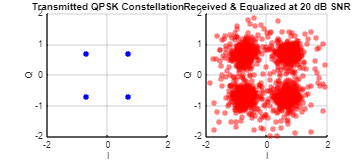

% OFDM and Rayleigh Fading Channel Simulation
clear; clc; close all;

% 1. OFDM System Parameters
numSubcarriers = 64;       % Number of subcarriers in OFDM block
numSymbols = 100;          % Number of OFDM symbols
snrDB = 20;                % Signal-to-Noise Ratio in dB

% 2. Generate Random Data & Map to QPSK Symbols
dataBits = randi([0, 1], numSubcarriers * numSymbols * 2, 1);
I = 2 * dataBits(1:2:end) - 1;
Q = 2 * dataBits(2:2:end) - 1;
qpskSymbols = (I + 1j * Q) / sqrt(2);

% Reshape into a matrix (Subcarriers x Symbols)
txDataMatrix = reshape(qpskSymbols, numSubcarriers, numSymbols);

% 3. Apply Inverse Fast Fourier Transform (IFFT) to create OFDM waveform
txTimeDomain = ifft(txDataMatrix, numSubcarriers);

% 4. Simulate Multipath Rayleigh Fading Channel + AWGN
% Create a simple 2-path Rayleigh fading channel impulse response
rayleighChannel = (randn(numSymbols, 1) + 1j * randn(numSymbols, 1)) / sqrt(2);

% Pass time-domain signal through the fading channel and add AWGN noise
rxTimeDomain = txTimeDomain .* rayleighChannel'; 
rxSignalNoisy = awgn(rxTimeDomain, snrDB, 'measured');

% 5. Receiver Side: Fast Fourier Transform (FFT) to recover symbols
rxDataMatrix = fft(rxSignalNoisy, numSubcarriers);

% Simple One-Tap Equalization (correcting for the fading channel distortion)
equalizedSymbols = rxDataMatrix ./ rayleighChannel';

% 6. Plotting the Results
figure('Color', 'white', 'Position', [100, 100, 900, 400]);

subplot(1, 2, 1);
scatter(real(txDataMatrix(:)), imag(txDataMatrix(:)), 30, 'b', 'filled', 'MarkerFaceAlpha', 0.5);
title('Transmitted QPSK Constellation');
xlabel('I'); ylabel('Q'); grid on; xlim([-2 2]); ylim([-2 2]);

subplot(1, 2, 2);
scatter(real(equalizedSymbols(:)), imag(equalizedSymbols(:)), 30, 'r', 'filled', 'MarkerFaceAlpha', 0.5);
title(sprintf('Received & Equalized at %d dB SNR', snrDB));
xlabel('I'); ylabel('Q'); grid on; xlim([-2 2]); ylim([-2 2]);